# COMPONENTS & PROPERTIES INPUTS PAGE

Use this page to load/edit the half car component inputs like springs,tires etc

** NOTE 

This script is divided into many different sections. The grouping is done based on some similarities. 

To run the sections individually (which will save time) click anywhere on the section and then click the 

`Run Section` button.

A section is demarcated by a blue border.

**NOTE - Throughout the Model the suffix "1" refers to the front end of the car and "2" refers to the rear end of the car

## `LEGEND`

% Comments (in green) can indicate notes or units 
"EDIT FIELD"; % Indicates a user input is expected

`--- INTERNAL ---` = Code below this heading is for internal use only 

`--- USER ---` = Code below this is is for the user to edit. It can also contain plotting commands for data visualization

## HALF CAR PROPERTIES

This section contains half car parameters like wheelbase, mass etc.,

**Instructions :-**

- *Use textbox to edit value *

- *Comment on right contains property name and unit*

### `--- USER ---` Properties

%%%%%%%%%%%%%%%%%%%%%%% Safety %%%%%%%%%%%%%%%%%%%%%%%%%%%%
A = exist('hcar','var');

if A == 0
    hcar = HCar;
end
clear A ans;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Half Car Properties

hcar.mass_sm = 400; % [Kg] | Suspended Mass
hcar.mass_sm_dis = 50; % [%] | Suspended Mass Distribution
hcar.Inertia = 600; % [Kgm^2] | Suspended Mass Inertia
hcar.Inertia_NSM_1 = 2.4; % [Kgm^2] | Unsprung Mass Inertia - Front
hcar.Inertia_NSM_2 = 3.2; % [Kgm^2] | Unsprung Mass Inertia - Rear
hcar.mass_usm_1 = 42; % [Kg] | Unsprung Mass - Front
hcar.mass_usm_2 = 42; % [Kg] | Unsprung Mass - Rear
hcar.w2w = 3; % [m] - Wheelbase
hcar.cg_SM_Height = 0.336; % [m] | CG Height - Suspended Mass
hcar.cg_USM_Height = 0.225; % [m] | CG Height - Unsprung Mass Front
hcar.cg_USM_Height2 = 0.225; % [m] | CG HEight - Unsprung Mass Rear
hcar.rh_1 = 0.067; % [m] | Ride Height - Front
hcar.rh_2 = 0.081; % [m] | Ride Height - Rear
hcar.a_RH_X = 0.25; % [m] | RH Measurement Point X Coordinate - Front
hcar.b_RH_X = -3.25; % [m] | RH Measurement Point X Coordinate - Rear

## COMPONENT PROPERTIES

Here all the individual components (springs,dampers etc.,) of the half car are considered

STRUCT Variable - `c`

### --- INTERNAL --- INITIALIZATION

% Spring Initialization
c.fSpring = Spring();
c.rSpring = Spring();

% Bumpstop Initialization
c.fBS = Bumpstop;
c.rBS = Bumpstop;

% Coilover Initialization
c.fCoil = Coilover;
c.rCoil = Coilover;

% Damper Initialization
c.fDamper = Damper;
c.rDamper = Damper;

% Tire Initialization
c.fTire = TireCus;
c.rTire = TireCus;

% Suspension Initialization
c.susp = AxleSuspension;

% Aerodynamics Initialization
c.aero = Aerodynamics;

### `--- USER ---` Springs

#### ***Important Instructions***

- For Force vs Deflection data template please refer to the excel sheet in folder Component Files-> Springs. **IMPORTANT** - Please make sure to follow this template.

- Units of Deflection --> **[m]**

- Units of Force --> **[N]**

- **IMPORTANT** - Please ensure that the first row of the excel sheet being important consists of only column names without any special characters. If there are any special characters (including space, you will get a warning. The software will NOT fail but you will get a warning.

- **IMPORTANT** - Incase you are editing the excel file, please make sure that it contains only 2 columns (1st one of deflection and 2nd one of force) and no other columns 

- Please ensure that the excel sheet is not open during importing. An error message will be displayed if the excel sheet is open in Microsoft Excel while the code to import the file is being run. 

- *Graphs plotted in [N] vs [mm] **only for convenience**. Units are still [m]*

% --- FRONT SPRINGS --- 
disp(" -------- FRONT SPRINGS -------- ");

 -------- FRONT SPRINGS -------- 


c.fSpring.freeLength = 0.2; % [m] | Free Length of Spring - Front
c.fSpring.stroke = 0.1; % [m] | Stroke of Spring - Front
    c.forceDefData  = readtable("LMP_Spring.xlsx") % Importing Force vs Deflection data

c = struct with fields:
          fSpring: [1×1 Spring]
          rSpring: [1×1 Spring]
              fBS: [1×1 Bumpstop]
              rBS: [1×1 Bumpstop]
            fCoil: [1×1 Coilover]
            rCoil: [1×1 Coilover]
          fDamper: [1×1 Damper]
          rDamper: [1×1 Damper]
            fTire: [1×1 TireCus]
            rTire: [1×1 TireCus]
             susp: [1×1 AxleSuspension]
             aero: [1×1 Aerodynamics]
     forceDefData: [6×2 table]
     forceVelData: [11×2 table]
               sr: [-1 -0.9000 -0.8000 -0.7000 -0.6000 -0.5000 -0.4000 -0.3000 -0.2000 -0.1000 0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1]
               fz: [200 400 600 800 1000]
             fx_f: [5×21 double]
             fx_r: [5×21 double]
    aeroMapImport: [2501×5 table]


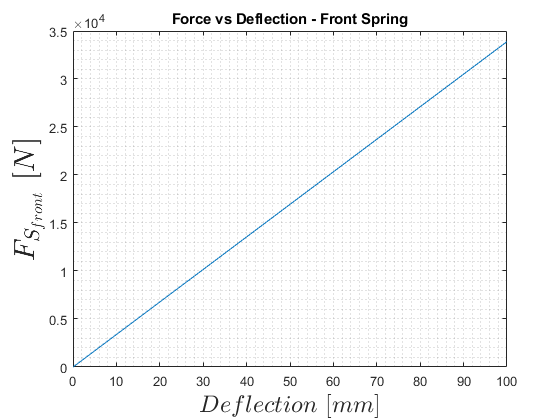

c.fSpring.forceDefData = [c.forceDefData.Variables];

plot(c.fSpring.forceDefData(:,1)*1000,c.fSpring.forceDefData(:,2));
title("Force vs Deflection - Front Spring");
ylabel({'$F_{S_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$Deflection\ [mm]$'},'Interpreter','latex','FontSize',18);
grid minor;



% --- REAR SPRINGS --- 
disp(" -------- REAR SPRINGS -------- ");

 -------- REAR SPRINGS -------- 


c.rSpring.freeLength = 0.2; % [m] | Free Length of Spring - Front
c.rSpring.stroke = 0.1; % [m] | Stroke of Spring - Front
    c.forceDefData  = readtable("LMP_Spring.xlsx") % Importing Force vs Deflection data

c = struct with fields:
          fSpring: [1×1 Spring]
          rSpring: [1×1 Spring]
              fBS: [1×1 Bumpstop]
              rBS: [1×1 Bumpstop]
            fCoil: [1×1 Coilover]
            rCoil: [1×1 Coilover]
          fDamper: [1×1 Damper]
          rDamper: [1×1 Damper]
            fTire: [1×1 TireCus]
            rTire: [1×1 TireCus]
             susp: [1×1 AxleSuspension]
             aero: [1×1 Aerodynamics]
     forceDefData: [6×2 table]
     forceVelData: [11×2 table]
               sr: [-1 -0.9000 -0.8000 -0.7000 -0.6000 -0.5000 -0.4000 -0.3000 -0.2000 -0.1000 0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1]
               fz: [200 400 600 800 1000]
             fx_f: [5×21 double]
             fx_r: [5×21 double]
    aeroMapImport: [2501×5 table]


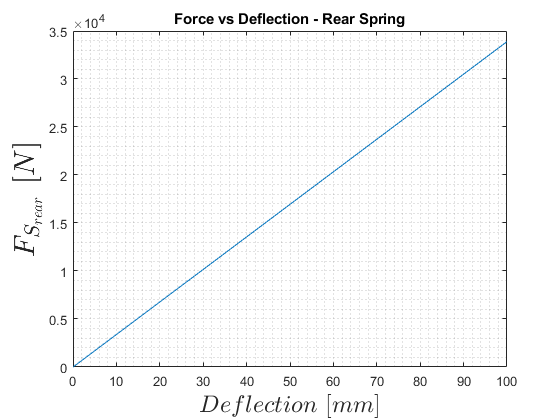

c.rSpring.forceDefData = [c.forceDefData.Variables];

plot(c.rSpring.forceDefData(:,1)*1000,c.rSpring.forceDefData(:,2));
title("Force vs Deflection - Rear Spring");
ylabel({'$F_{S_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$Deflection\ [mm]$'},'Interpreter','latex','FontSize',18);
grid minor;

### `--- USER ---` Bumpstops

#### ***Important Instructions***

- For Force vs Deflection data template please refer to the excel sheet in folder Component Files-> Bumpstops. **IMPORTANT** - Please make sure to follow this template.

- Units of Deflection --> **[m]**

- Units of Force --> **[N]**

- **IMPORTANT** - Please ensure that the first row of the excel sheet being important consists of only column names without any special characters. If there are any special characters (including space, you will get a warning. The software will NOT fail but you will get a warning.

- **IMPORTANT** - Incase you are editing the excel file, please make sure it consists of 2 columns (1st of the deflection and 2nd of the force) and no other columns. 

- Please ensure that the excel sheet is not open during importing. An error message will be displayed if the excel sheet is open in Microsoft Excel while the code to import the file is being run. 

- *Graphs plotted in [N] vs [mm] **only for convenience**. Units are still [m]*

% --- FRONT BUMPSTOPS --- 
disp(" -------- FRONT BUMPSTOPS -------- ");

 -------- FRONT BUMPSTOPS -------- 


c.fBS.freeLength = 0.015; % [m] | Free Length of Bumpstop
c.fBS.stroke = 0.0145; % [m] | Stroke of Bumpstop
    c.forceDefData  = readtable("LMP_Bumpstop.xlsx") % Importing Force vs Deflection data

c = struct with fields:
          fSpring: [1×1 Spring]
          rSpring: [1×1 Spring]
              fBS: [1×1 Bumpstop]
              rBS: [1×1 Bumpstop]
            fCoil: [1×1 Coilover]
            rCoil: [1×1 Coilover]
          fDamper: [1×1 Damper]
          rDamper: [1×1 Damper]
            fTire: [1×1 TireCus]
            rTire: [1×1 TireCus]
             susp: [1×1 AxleSuspension]
             aero: [1×1 Aerodynamics]
     forceDefData: [29×2 table]
     forceVelData: [11×2 table]
               sr: [-1 -0.9000 -0.8000 -0.7000 -0.6000 -0.5000 -0.4000 -0.3000 -0.2000 -0.1000 0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1]
               fz: [200 400 600 800 1000]
             fx_f: [5×21 double]
             fx_r: [5×21 double]
    aeroMapImport: [2501×5 table]


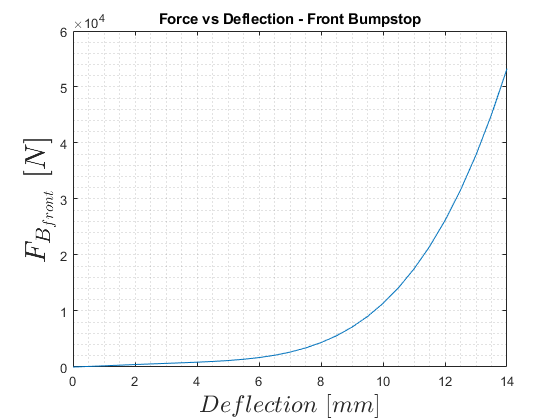

c.fBS.forceDefData = [c.forceDefData.Variables];

plot(c.fBS.forceDefData(:,1)*1000,c.fBS.forceDefData(:,2));
title("Force vs Deflection - Front Bumpstop");
ylabel({'$F_{B_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$Deflection\ [mm]$'},'Interpreter','latex','FontSize',18);
grid minor;


% --- REAR BUMPSTOPS --- 
disp(" -------- REAR BUMPSTOPS -------- ");

 -------- REAR BUMPSTOPS -------- 


c.rBS.freeLength = 0.015; % [m] | Free Length of Bumpstop
c.rBS.stroke = 0.0145; % [m] | Stroke of Bumpstop
    c.forceDefData  = readtable("LMP_Bumpstop.xlsx") % Importing Force vs Deflection data

c = struct with fields:
          fSpring: [1×1 Spring]
          rSpring: [1×1 Spring]
              fBS: [1×1 Bumpstop]
              rBS: [1×1 Bumpstop]
            fCoil: [1×1 Coilover]
            rCoil: [1×1 Coilover]
          fDamper: [1×1 Damper]
          rDamper: [1×1 Damper]
            fTire: [1×1 TireCus]
            rTire: [1×1 TireCus]
             susp: [1×1 AxleSuspension]
             aero: [1×1 Aerodynamics]
     forceDefData: [29×2 table]
     forceVelData: [11×2 table]
               sr: [-1 -0.9000 -0.8000 -0.7000 -0.6000 -0.5000 -0.4000 -0.3000 -0.2000 -0.1000 0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1]
               fz: [200 400 600 800 1000]
             fx_f: [5×21 double]
             fx_r: [5×21 double]
    aeroMapImport: [2501×5 table]


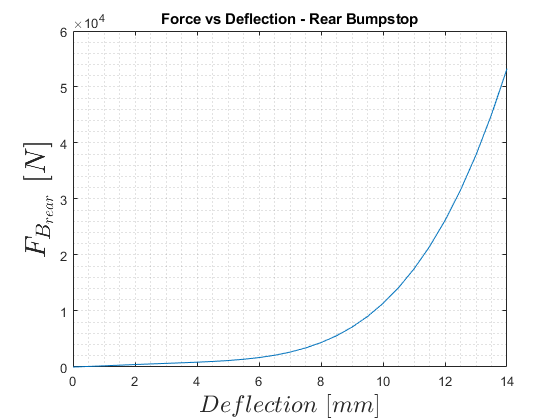

c.rBS.forceDefData = [c.forceDefData.Variables];

plot(c.rBS.forceDefData(:,1)*1000,c.rBS.forceDefData(:,2));
title("Force vs Deflection - Rear Bumpstop");
ylabel({'$F_{B_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$Deflection\ [mm]$'},'Interpreter','latex','FontSize',18);
grid minor;

### `--- USER ---` Coilovers

% --- FRONT COILOVERS --- 
disp(" -------- FRONT COILOVER -------- ");

 -------- FRONT COILOVER -------- 


c.fCoil.freeLength = 0.449; % [m] | Free Length of Coilover
c.fCoil.stroke = 0.048; % [m] | Stroke of Coilover
c.fCoil.bsGap = 0.038; % [m] | Bumpstop Gap
c.fCoil.springGap = 0.016; % [m] | Spring Gap

% --- REAR COILOVERS --- 
disp(" -------- REAR COILOVER -------- ");

 -------- REAR COILOVER -------- 


c.rCoil.freeLength = 0.449; % [m] | Free Length of Coilover
c.rCoil.stroke = 0.048; % [m] | Stroke of Coilover
c.rCoil.bsGap = 0.038; % [m] | Bumpstop Gap
c.rCoil.springGap = 0.016; % [m] | Spring Gap


%%%%%%%%%%%%%%%%%%%%%% --- INTERNAL --- Coilover Conditioning %%%%%%%%%%%%%
% Front Coilover Conditioning
c.fCoil.spring = c.fSpring;
c.fCoil.bumpStop = c.fBS;
c.fCoil = c.fCoil.Combine_ForceDefData();

% Rear Coilover Conditioning
c.rCoil.spring = c.rSpring;
c.rCoil.bumpStop = c.rBS;
c.rCoil = c.rCoil.Combine_ForceDefData();

### `--- USER ---` Dampers

#### ***Important Instructions***

- For Force vs Shaft Velocity data template please refer to the excel sheet in folder Component Files-> Dampers. **IMPORTANT** - Please make sure to follow this template. 

- Units of Shaft Velocity --> **[m/s]**

- Units of Force --> **[N]**

- **IMPORTANT** - Please ensure that the first row of the excel sheet being important consists of only column names without any special characters. If there are any special characters (including space, you will get a warning. The software will NOT fail but you will get a warning.

- **IMPORTANT** - Incase you are editing the excel file, please make sure it consists of 2 columns (1st of the shaft velocity and 2nd of the force) and no other columns. 

- Please ensure that the excel sheet is not open during importing. An error message will be displayed if the excel sheet is open in Microsoft Excel while the code to import the file is being run. 

- *Graphs plotted in [N] vs [mm/s] **only for convenience**. Units are still [m/s]*

- *** NOTE : mps = meter/second!*

% --- FRONT DAMPERS ---
disp(" -------- FRONT DAMPER  -------- ");

 -------- FRONT DAMPER  -------- 


c.fDamper.freeLength = 0.35; % [m] | Free Length of Damper
c.fDamper.stroke = 0.15; % [m] | Stroke of Damper
c.fDamper.staticGasForce = 0; % [N] | Static Gas Pressure Force
    c.forceVelData = readtable("LMP_Damper.xlsx")

c = struct with fields:
          fSpring: [1×1 Spring]
          rSpring: [1×1 Spring]
              fBS: [1×1 Bumpstop]
              rBS: [1×1 Bumpstop]
            fCoil: [1×1 Coilover]
            rCoil: [1×1 Coilover]
          fDamper: [1×1 Damper]
          rDamper: [1×1 Damper]
            fTire: [1×1 TireCus]
            rTire: [1×1 TireCus]
             susp: [1×1 AxleSuspension]
             aero: [1×1 Aerodynamics]
     forceDefData: [29×2 table]
     forceVelData: [11×2 table]
               sr: [-1 -0.9000 -0.8000 -0.7000 -0.6000 -0.5000 -0.4000 -0.3000 -0.2000 -0.1000 0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1]
               fz: [200 400 600 800 1000]
             fx_f: [5×21 double]
             fx_r: [5×21 double]
    aeroMapImport: [2501×5 table]


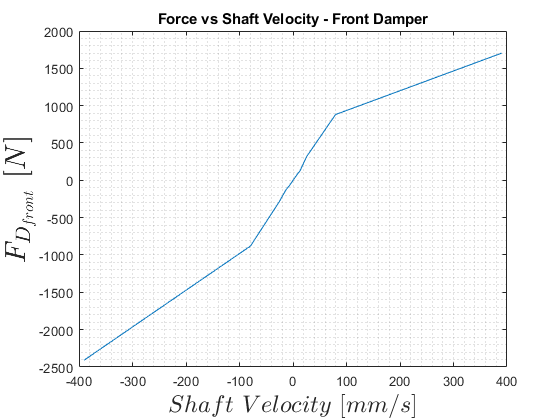

c.fDamper.forceVelData = c.forceVelData.Variables;

plot(c.fDamper.forceVelData(:,1)*1000,c.fDamper.forceVelData(:,2));
title("Force vs Shaft Velocity - Front Damper");
ylabel({'$F_{D_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$Shaft\ Velocity \ [mm/s]$'},'Interpreter','latex','FontSize',18);
grid minor;


% --- REAR DAMPERS ---
disp(" -------- REAR DAMPER -------- ");

 -------- REAR DAMPER -------- 


c.rDamper.freeLength = 0.35; % [m] | Free Length of Damper
c.rDamper.stroke = 0.15; % [m] | Stroke of Damper
c.rDamper.staticGasForce = 0; % [N] | Static Gas Pressure Force
    c.forceVelData = readtable("LMP_Damper.xlsx")

c = struct with fields:
          fSpring: [1×1 Spring]
          rSpring: [1×1 Spring]
              fBS: [1×1 Bumpstop]
              rBS: [1×1 Bumpstop]
            fCoil: [1×1 Coilover]
            rCoil: [1×1 Coilover]
          fDamper: [1×1 Damper]
          rDamper: [1×1 Damper]
            fTire: [1×1 TireCus]
            rTire: [1×1 TireCus]
             susp: [1×1 AxleSuspension]
             aero: [1×1 Aerodynamics]
     forceDefData: [29×2 table]
     forceVelData: [11×2 table]
               sr: [-1 -0.9000 -0.8000 -0.7000 -0.6000 -0.5000 -0.4000 -0.3000 -0.2000 -0.1000 0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1]
               fz: [200 400 600 800 1000]
             fx_f: [5×21 double]
             fx_r: [5×21 double]
    aeroMapImport: [2501×5 table]


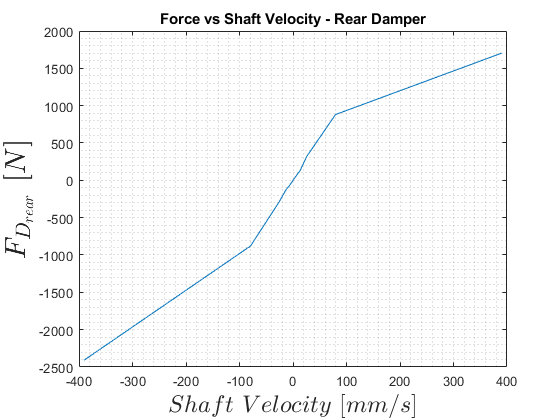

c.rDamper.forceVelData = c.forceVelData.Variables;

plot(c.rDamper.forceVelData(:,1)*1000,c.rDamper.forceVelData(:,2));
title("Force vs Shaft Velocity - Rear Damper");
ylabel({'$F_{D_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$Shaft\ Velocity \ [mm/s]$'},'Interpreter','latex','FontSize',18);
grid minor;

### `--- USER ---` Tires

**IMPORTANT**

- Editing tire pacejka coefficients isn't straight forward. I didn't invest time in it because OptimumTire Add-in is not working with Matlab.

- If user wants to edit the tire coefficients then please navigate to `"Classes" --> "Base Component Classes" --> "TireCus.m"`

% --- FRONT TIRES ---
disp(" -------- FRONT TIRE-------- ");

 -------- FRONT TIRE-------- 


c.fTire.kt = 200000; % [N/m] | Vertical Stiffness
c.fTire.dt = 8; % [Ns/m] | Vertical Damping Coefficient
c.fTire.unloadedRadius = 0.225; % [m] | Unloaded Radius
c.fTire.relX = 0.5; % [m] | Longitudinal Relaxation Length
c.fTire.mf = c.fTire.Init_MF_Coeff(); 
disp("To edit coefficients navigate to TireCus.m class");

To edit coefficients navigate to TireCus.m class


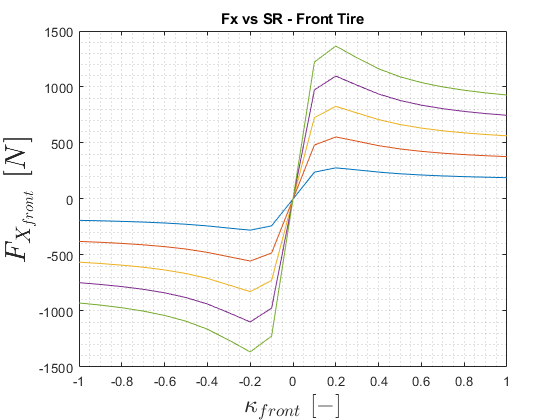


c.sr = -1:0.1:1;
c.fz = 200:200:1000;
figure();
for i = 1:length(c.fz)
    c.fx_f(i,:) = MF5ss_eval(c.fz(i),c.sr,0,0,c.fTire.mf);
    plot(c.sr,c.fx_f(i,:));
    hold on;
end
title("Fx vs SR - Front Tire");
ylabel({'$F_{X_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$\kappa_{front} \ [-]$'},'Interpreter','latex','FontSize',18);
grid minor;


% --- REAR TIRES ---
disp(" -------- REAR TIRE-------- ");

 -------- REAR TIRE-------- 


c.rTire.kt = 200000; % [N/m] | Vertical Stiffness
c.rTire.dt = 8; % [Ns/m] | Vertical Damping Coefficient
c.rTire.unloadedRadius = 0.225; % [m] | Unloaded Radius
c.rTire.relX = 0.5; % [m] | Longitudinal Relaxation Length
c.rTire.mf = c.rTire.Init_MF_Coeff();disp("To edit coefficients navigate to TireCus.m class");

To edit coefficients navigate to TireCus.m class


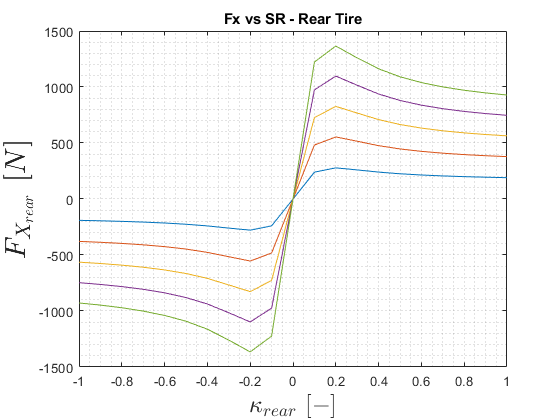


figure();
for i = 1:length(c.fz)
    c.fx_r(i,:) = MF5ss_eval(c.fz(i),c.sr,0,0,c.rTire.mf);
    plot(c.sr,c.fx_r(i,:));
    hold on;
end
title("Fx vs SR - Rear Tire");
ylabel({'$F_{X_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$\kappa_{rear} \ [-]$'},'Interpreter','latex','FontSize',18);
grid minor;clear i;

### `--- USER ---` Suspension

% --- FRONT SUSPENSION ---
disp(" -------- FRONT SUSPENSION -------- ");

 -------- FRONT SUSPENSION -------- 


c.susp.vsal_1 = 3.6; % [m] | Side View VSAL
c.susp.ich_1 = 0.35; % [m] | Side View IC Height

% --- REAR SUSPENSION ---
disp(" -------- REAR SUSPENSION -------- ");

 -------- REAR SUSPENSION -------- 


c.susp.vsal_2 = 3.6; % [m] | Side View VSAL
c.susp.ich_2 = 0.35; % [m] | Side View IC Height


### `--- USER ---` Aerodynamics

#### ***Important Instructions***

- For Aeromap template please refer to the excel sheet in folder Component Files-> Aerodynamics

- **IMPORTANT CHANGE**:- Units of Ride Heights --> **[mm]**

- Units of Coefficients --> **[-]**

- Units of Aerobalance --> **[%]**

- Please ensure that the first row of the excel sheet being important consists of only column names without any special characters. If there are any special characters (including space, you will get a warning. The software will NOT fail but you will get a warning.

- Please ensure that the excel sheet is not open during importing. An error message will be displayed if the excel sheet is open in Microsoft Excel while the code to import the file is being run. 

% --- VEHICLE AERODYNAMICS ---
c.aero.fArea = 1; % [m^2] | Frontal Area
c.aero.airDensity = 1.225; % [Kgm^3] | Air Density
    c.aeroMapImport = readtable('LMP_Aero.xlsx')

c = struct with fields:
          fSpring: [1×1 Spring]
          rSpring: [1×1 Spring]
              fBS: [1×1 Bumpstop]
              rBS: [1×1 Bumpstop]
            fCoil: [1×1 Coilover]
            rCoil: [1×1 Coilover]
          fDamper: [1×1 Damper]
          rDamper: [1×1 Damper]
            fTire: [1×1 TireCus]
            rTire: [1×1 TireCus]
             susp: [1×1 AxleSuspension]
             aero: [1×1 Aerodynamics]
     forceDefData: [29×2 table]
     forceVelData: [11×2 table]
               sr: [-1 -0.9000 -0.8000 -0.7000 -0.6000 -0.5000 -0.4000 -0.3000 -0.2000 -0.1000 0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1]
               fz: [200 400 600 800 1000]
             fx_f: [5×21 double]
             fx_r: [5×21 double]
    aeroMapImport: [2501×5 table]


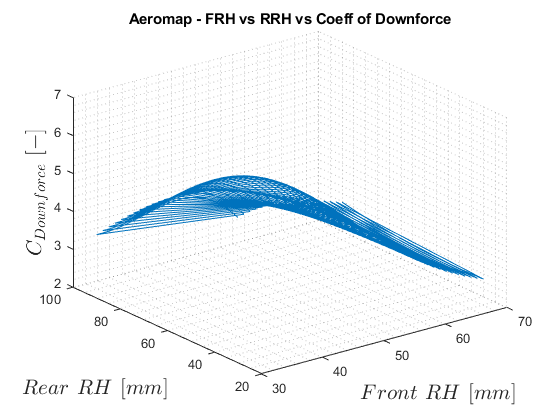

c.aero.aeromap = [c.aeroMapImport.Variables];

%%%%%%% INTERNAL %%%%%%%
c.aero.cDown = c.aero.aeromap(:,3);
c.aero.cDrag = c.aero.aeromap(:,4);
c.aero.cDist = c.aero.aeromap(:,5);

figure();
plot3(c.aero.aeromap(:,1),c.aero.aeromap(:,2),c.aero.cDown);
title("Aeromap - FRH vs RRH vs Coeff of Downforce");
zlabel({'$C_{Downforce}\ [-]$'},'Interpreter','latex','FontSize',16);
ylabel({'$Rear\ RH \ [mm]$'},'Interpreter','latex','FontSize',16);
xlabel({'$Front\ RH\ [mm]$'},'Interpreter','latex','FontSize',16);
grid minor;

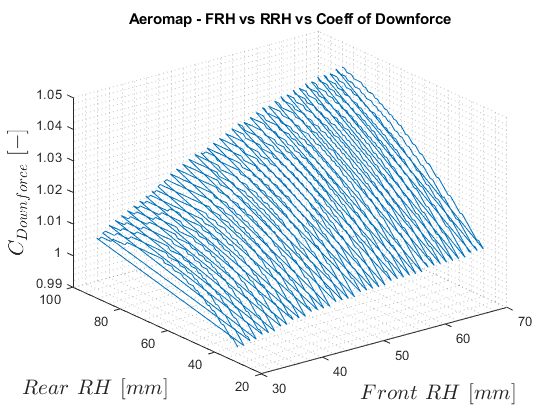


figure();
plot3(c.aero.aeromap(:,1),c.aero.aeromap(:,2),c.aero.cDrag);
title("Aeromap - FRH vs RRH vs Coeff of Downforce");
zlabel({'$C_{Downforce}\ [-]$'},'Interpreter','latex','FontSize',16);
ylabel({'$Rear\ RH \ [mm]$'},'Interpreter','latex','FontSize',16);
xlabel({'$Front\ RH\ [mm]$'},'Interpreter','latex','FontSize',16);
grid minor;

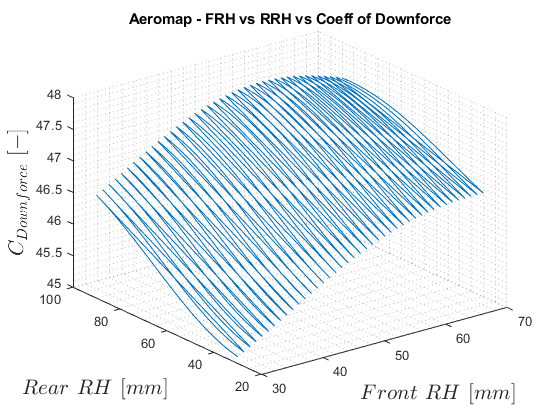


figure();
plot3(c.aero.aeromap(:,1),c.aero.aeromap(:,2),c.aero.cDist);
title("Aeromap - FRH vs RRH vs Coeff of Downforce");
zlabel({'$C_{Downforce}\ [-]$'},'Interpreter','latex','FontSize',16);
ylabel({'$Rear\ RH \ [mm]$'},'Interpreter','latex','FontSize',16);
xlabel({'$Front\ RH\ [mm]$'},'Interpreter','latex','FontSize',16);
grid minor;

%%%%%%%%%%%%%%%%%% --- INTERNAL --- HALFCAR CONDITIONING %%%%%%%%%%%%%%%%%%
% Updating all half car component properties
hcar.coil1 = c.fCoil;
hcar.coil2 = c.rCoil;
hcar.damper1 = c.fDamper;
hcar.damper2 = c.rDamper;
hcar.tire1 = c.fTire;
hcar.tire2 = c.rTire;
hcar.axleSusp = c.susp;
hcar.aero = c.aero;

[hcar.mass_sm_1,hcar.mass_sm_2] = hcar.Compute_AxleMass();
[hcar.dis_a12cg,hcar.dis_a22cg] = hcar.Compute_DisFromCG();
[hcar.a_RH,hcar.b_RH] = hcar.Compute_RHPoint_DisFromCG();
hcar = hcar.Compute_Hyp();
